# Identify iron loss

The iron loss model described in "iron_loss.m" is identified by this script.


$$V = |f I_a|$$



$$Q_{iron} = c_h V + c_J V^2 + c_{ex} V^{1.5}$$


## import data

execute simlink model before.

### actual frequency (Hz)

f = simOut.logsout.getElement("f").Values.Data;

### actual current (A)

Id = simOut.logsout.getElement("Idq").Values.Data(:,1);
Iq = simOut.logsout.getElement("Idq").Values.Data(:,2);
Ia = sqrt(Id.^2+Iq.^2);

### actual loss (W)

Qiron = simOut.logsout.getElement("Qiron_base").Values.Data;

## identification

model = fittype( ...
    @(ch,cJ,cex,f,Ia) iron_loss(abs(f),abs(Ia),ch,cJ,cex), ...
    "independent",{'f','Ia'});

sf = fit([Ia,f],Qiron, ...
    model, ...
    "Start",[0,0,0]);

ch = sf.ch;
cJ = sf.cJ;
cex = sf.cex;

format shorte
disp([ch,cJ,cex]);

   2.1950e-02   1.3968e-06  -2.3721e-04



## verify the identified model

### create mesh from identified model

[f_model,Ia_model] = meshgrid( ...
    linspace(min(f),max(f),21), ...
    linspace(min(Ia),max(Ia),21));

Qiron_model = iron_loss(f_model,Ia_model,ch,cJ,cex);

### plotting

#### speed current, and loss

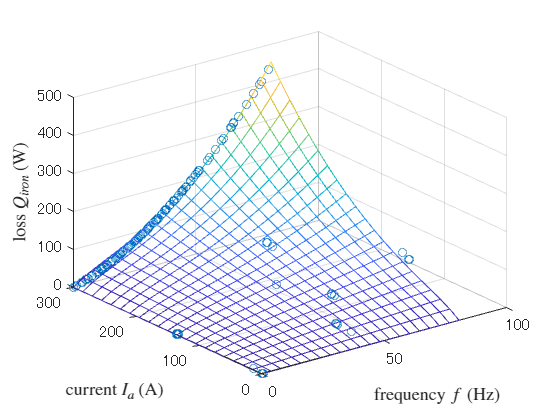

figure("Name","frequency - current - loss");
scatter3(abs(f),abs(Ia),Qiron); hold on;
mesh(f_model,Ia_model,Qiron_model,"FaceAlpha",0);
xlabel("frequency $f$ (Hz)","Interpreter","latex");
ylabel("current $I_a$ (A)","Interpreter","latex");
zlabel("loss $Q_{iron}$ (W)","Interpreter","latex");
ax = gca(); ax.FontSize = 12;